# Hands-On -  MA  Stochastic Process: Estimation of the Correlation Function and the Spectral Power Density from Data

## Introduction

Given a stationary (in weak sense) white noise stochastic process


$$$\eta(\cdot) \sim WN(0,\lambda^2)$$$


with mean value $\text{E}\left[\eta(t)\right]=0$ and variance $\sigma^2_{\eta} = \lambda^2$, it is well known that a **Moving Average stationary stochastic process MA(1)** is defined as


$$MA(1) \, \colon \quad
v(t) = \eta(t) + c \, \eta(t-1)$$


The autocorrelation function of the stochastic process MA(1) takes on the expression


$$MA(1) \, \colon \,
\left \{
\begin{array}{l}
\gamma(0) = \left (1+c^2 \right )\lambda^2\\
  \\
\gamma(1)=c \, \lambda^2 \\
  \\
\gamma(k)=0 , \, \forall \, k > 1
\end{array}
\right .$$


and the corresponding **spectral power density** is


$$\Gamma(\omega) = 
\sum_{\tau=-\infty}^{+\infty} 
\gamma(\tau) e^{-j \omega \tau} \, = \, \left (1+c^2+ 2 c \cos \omega \right )
\lambda^2, \quad
\forall \, \omega \in [-\pi,\pi]$$


### A Practical Issue

Suppose we now acquire a finite number $N$ of samples from a WSS stationary MA(1) process. How can we estimate the autocorrelation function and spectrum from the available data?

## Sampled Estimator of the Mean Value, the Variance and the Autocorrelation Function

We have already analysed the sampled estimators of mean value and variance. We recall them for convenience.

### Sample Average Estimator 

Given $N$ random variables $\, v(1)\,,\; v(2)\,,\; \ldots\,,\; v(N) \,$such that


$$\text{E} \left[ v(i) \right] = \mu_v\, , \quad i=1\,,\;2\,,\; \ldots\,,\; N$$


(i.e., with the same mean value) and						


$$\text{E} \left\{ \left[  v(i) - \mu_v \right] \, \left[ v(j) - \mu_v \right]\right\} = 0 \;, \quad \forall i \ne j$$


(i.e., the data are mutually uncorrelated), the **sampled-average estimator**					

				
$$\hat{\mu}_{v} = \displaystyle \frac{1}{N}\, \sum_{i=1}^{N} v(i) $$


is an **unbiased estimator**, i.e. 


$$\text{E} \left[ \hat{\mu_{v}}\right] = \mu_{v}$$


### The Sample Variance

The sample variance of $N$ observations $\{v_i\}, i=1,\ldots,N$ of the random variable $V$ with known mean $\mu_v$ is defined as 


$$ \hat \sigma^2_{\mu_v,N}={\frac {1}{N}}\sum _{i=1}^{N}(v_{i}-\mu_v)^2.$$


We have added the subindex $\mu$ to indicate that we used the exact value of the mean to calculate the variance. 

In practice, **the mean value is often unknown** and replaced by the sample mean. In that case the sample variance is defined as


$$ \hat \sigma^2_N={\frac {1}{N-1}}\sum _{i=1}^{N}(v_{i}-\hat \mu_N)^2$$


### The Sample Autocorrelation Function

Given $N$ observations $\{v_i\}, i=1,\ldots,N$ of the random variable $V$ with **null mean value** $\mu_v = \text{E}\left[ v_i \right] = 0 \; \forall i$, the autocorrelation function $\gamma_{v}(\tau)$ can be estimated by mean of the following expression


$$\hat{\gamma}_v (\tau) = \left\{ \begin{array}{lcl}
\displaystyle \frac{1}{N-\tau} \sum_{n=0}^{N-\tau-1}\, v(n)\cdot v(n+\tau) & \quad & \tau \ge 0 \\
\hat{\gamma}_v(-\tau) & \quad & \tau <0
\end{array} \right. \qquad \left| \tau \right| \le N-1$$


It can be proven that it is an **unbiased estimator **(refer to [1] for details). Moreover, it can be proven that the variance of the estimate converges to zero as $N \to \infty$, so the estimate $\hat{\gamma}(\tau)$ is a **consistent estimate** of $\gamma(\tau)$ (refer to [1] for details).

## Estimated Autocorrelation Function from Data

Let us generate $N$ samples of a WSS stationary MA(1) stochastic process, with zero mean and variance $\lambda^2$.

Collect the data and then apply the sampled estimators.

clear variables
close all
clc

### Generate and Collect the Samples

Remember


$$MA(1) \, \colon \quad
v(t) = \eta(t) + c \, \eta(t-1)$$


Ndata = 11000;    % select how many samples to collect and store

% dato che il transitorio e` di due campioni, considero molti dati, cosi`
% che la loro influenza sia minima

varWG = 3.5;      % select the white noise variance

WGsamples = sqrt(varWG)*randn(Ndata+1,1); % let's generate the white noise samples
WG_eta = WGsamples(2:end);    % the samples for the "eta(t)" array
WG_eta1 = WGsamples(1:end-1); % the samples for the "eta(t-1)" array

% i due array hanno uno shift temporale di 1

c_MA = 0.5;     % select the value of the MA coeff. c
c_negMA = -c_MA; % let's consider also the MA(1) process with coeff. -c


**Question**: what happens if we choose $c =0$ ? What kind of stochastic process is it if we choose $c=0$?

### The MA(1) processes

Let's generate the data from the MA(1) processes

 % the MA processes
 MA1 = WG_eta + c_MA * WG_eta1;    % eta(t) +c*eta(t-1)
 MA2 = WG_eta + c_negMA * WG_eta1; % eta(t) -c*eta(t-1)


Let's estimate the mean value and the variance for the first MA process

av_valMA1 = mean(MA1)      % the average value for the 1st MA process

av_valMA1 = -0.0339


sampled_varMA1 = var(MA1)  % the sampled variance

sampled_varMA1 = 4.3526

The theoretical variance value $\gamma(0) = \left (1+c^2 \right )\lambda^2$

gamma0_MA1 = (1+c_MA.^2)*varWG

gamma0_MA1 = 4.3750

Let's estimate the mean value and the variance for the second MA process

av_valMA2 = mean(MA2)      % the average value for the 1st MA process

av_valMA2 = -0.0116


sampled_varMA2 = var(MA2)  % the sampled variance

sampled_varMA2 = 4.3983

The theoretical variance value $\gamma(0) = \left (1+c^2 \right )\lambda^2$

gamma0_MA2 = (1+c_negMA.^2)*varWG

gamma0_MA2 = 4.3750

Run more than once, varying the variance of the process. Observe the convergence of the sampled estimates of the mean vakue and the variance to the effective values, when increasing the number of collected data.

**Note**: Both MA processes have the same theoretical variance, but the variance estimates take different values. How come? Any explanation?

### **What About the Autocorrelation Function?**

#### **The First MA Process**

Ncorr1 =96; % select the max value of tau in the estimation formula

Check if the maximum value for the lag $\tau$ is respecting the constraint $|\tau| \le N-1$, with $N$ the amount of available data.

errMSG = 'The max lag must be less or equal to (N-1), with N the amount of available data!'; % error message
assert((Ncorr1 <= (Ndata-1)), errMSG)

Let evaluate the estimate, using the MATLAB command `xcorr().`

Have a look to the command input and output variables, and to some application examples, using 

[gamma_v1, lags_v1] = xcorr(MA1, Ncorr1,'unbiased'); 
% unbiased estimation of the autocorr. function

Now let's plot 

- the acquired samples of the MA(1) process

- the samples of the estimated autocorrelation function

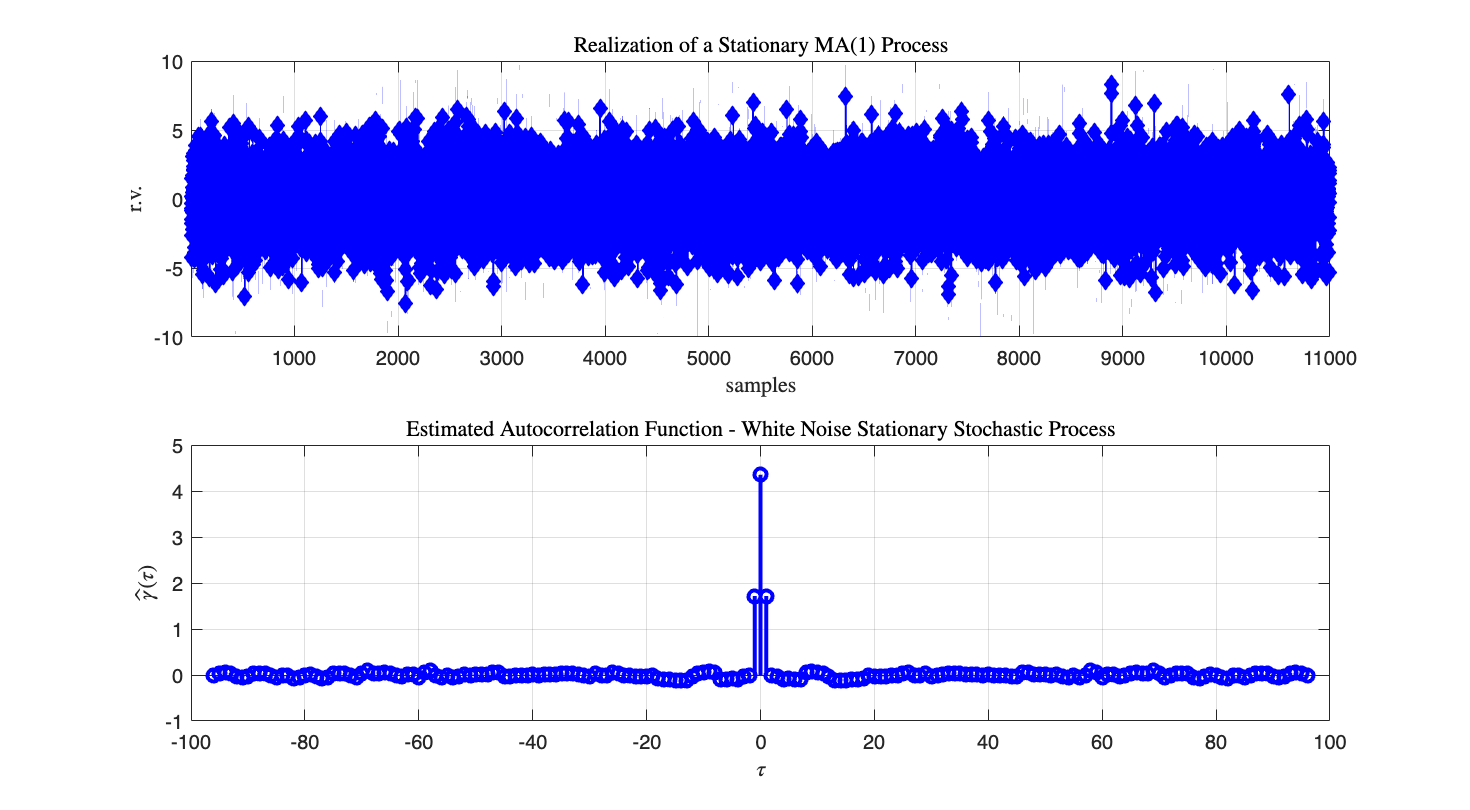

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);

subplot(2,1,1);
plot(MA1,'db-','MarkerSize',6, 'MarkerFaceColor','b','LineWidth',1.0);grid on;
title('Realization of a Stationary MA$(1)$ Process', 'Interpreter','latex');
xlabel('samples', 'Interpreter','latex');ylabel('r.v.', 'Interpreter','latex');
xlim([1, Ndata]); % setting the extremum values on the x-axis[']]]=

subplot(2,1,2);
stem(lags_v1, gamma_v1,'b', 'LineWidth',2);grid on;
xlabel('$\tau$', 'Interpreter','latex');ylabel('$\hat{\gamma}(\tau)$',...
    'Interpreter','latex');
title('Estimated Autocorrelation Function - White Noise Stationary Stochastic Process',...
    'Interpreter','latex');

**Note**: the estimated autcorrelation function has non-zero samples only for $\tau=0$ and $|\tau|=1$, as it should be according the theoretical analysis of the MA(1) autocorrelation function. Verify this feature in the lower plot, zooming around the $\tau=0$ zone if needed.

#### **The Second MA Process**

Ncorr2 = Ncorr1;% select the same max value of tau in the estimation formula as in MA1

Check if the maximum value for the lag $\tau$ is respecting the constraint $|\tau| \le N-1$, with $N$ the amount of available data.

errMSG = 'The max lag must be less or equal to (N-1), with N the amount of available data!'; % error message
assert((Ncorr2 <= (Ndata-1)), errMSG)

Let evaluate the estimate, using the MATLAB command `xcorr().`

Have a look to the command input and output variables, and to some application examples, using 

[gamma_v2, lags_v2] = xcorr(MA2, Ncorr2,'unbiased'); 
% unbiased estimation of the autocorr. function

Now let's plot 

- the acquired samples of the MA(1) process

- the samples of the estimated autocorrelation function

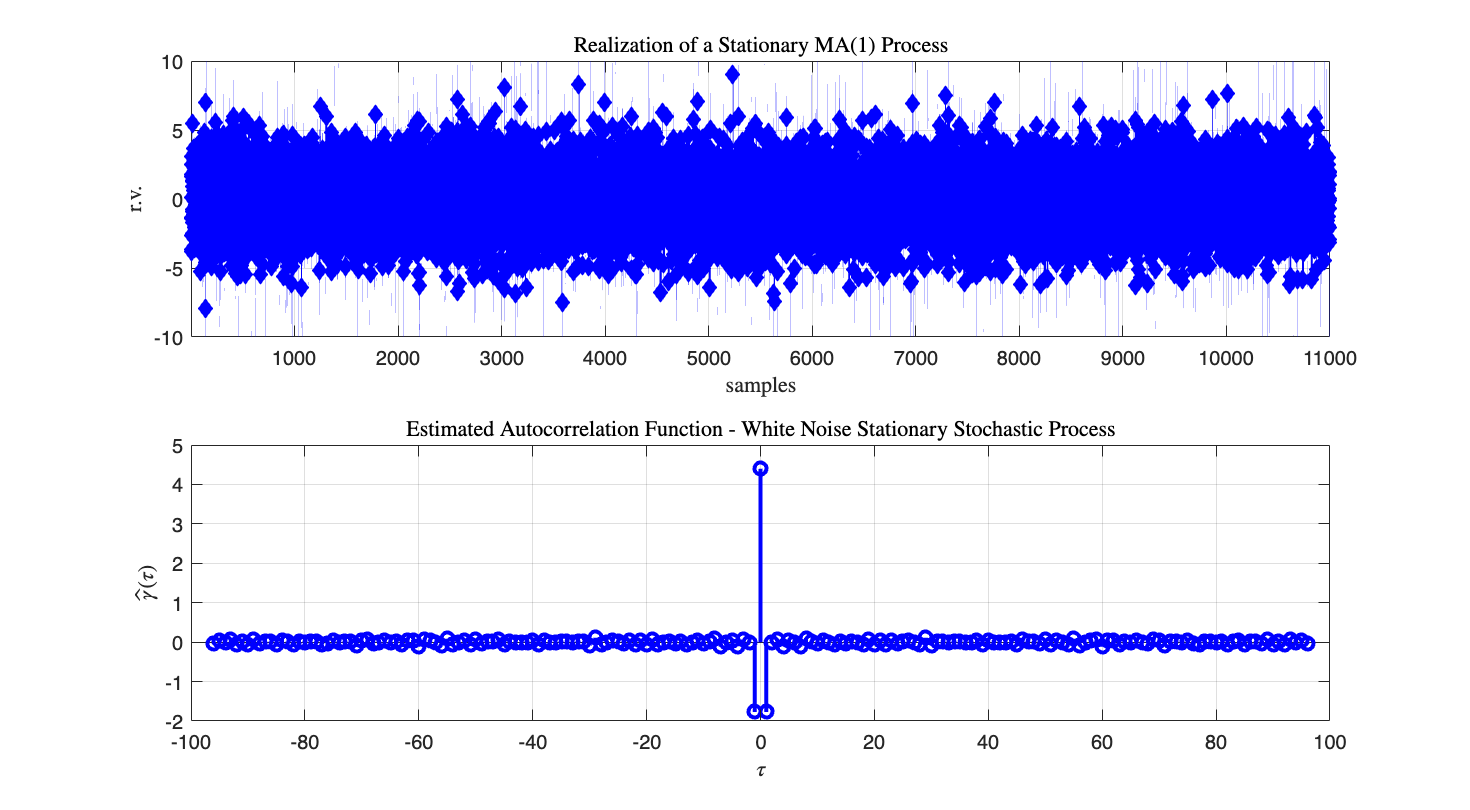

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);

subplot(2,1,1);
plot(MA2,'db-','MarkerSize',6, 'MarkerFaceColor','b','LineWidth',1.0);grid on;
title('Realization of a Stationary MA$(1)$ Process', 'Interpreter','latex');
xlabel('samples', 'Interpreter','latex');ylabel('r.v.', 'Interpreter','latex');
xlim([1, Ndata]); % setting the extremum values on the x-axis[']]]=

subplot(2,1,2);
stem(lags_v2, gamma_v2,'b', 'LineWidth',2);grid on;
xlabel('$\tau$', 'Interpreter','latex');ylabel('$\hat{\gamma}(\tau)$',...
    'Interpreter','latex');
title('Estimated Autocorrelation Function - White Noise Stationary Stochastic Process',...
    'Interpreter','latex');

**Note**: the estimated autcorrelation function has non-zero samples only for $\tau=0$ and $|\tau|=1$, as it should be according the theoretical analysis of the MA(1) autocorrelation function. Verify this feature in the lower plot, zooming around the $\tau=0$ zone if needed.

### Comparison of the MA(1) Processes

- Given two $\text{MA}(1)$ processes, both with the same $|c|$ coefficient value, how do the realizations of the processes look like? 

- Is the realisation with coefficient $c$ recognisable from that with the opposite coefficient $-c$ ? 

Let's put toghether both the realizations of the two MA processes, and the corresponding autocorrelation function estimates.

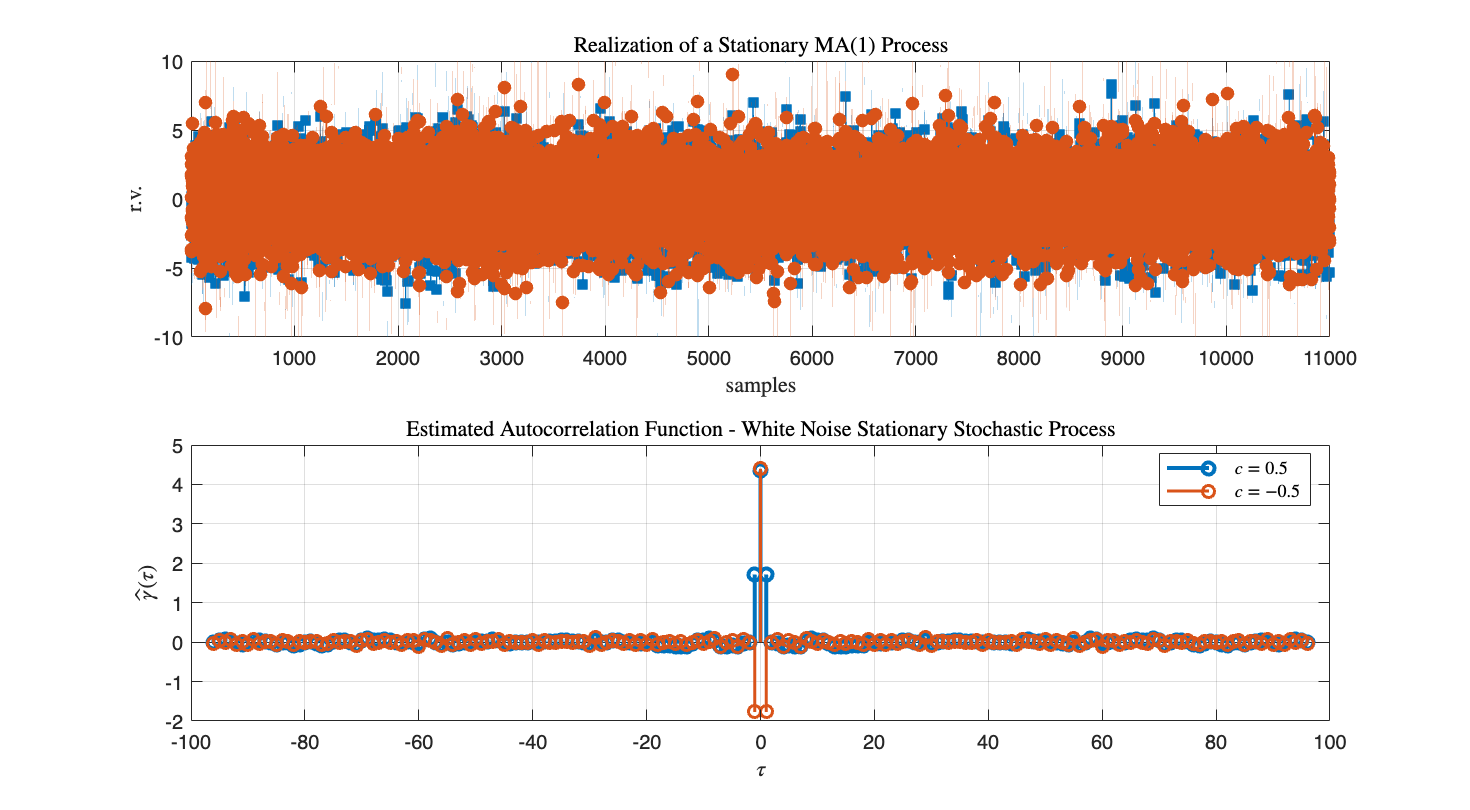

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);
% ---
subplot(2,1,1); % the realizations of the MA processes

hp1 = plot(MA1,'LineWidth',0.75, 'LineStyle','-');
set(hp1,'Marker', 'square','MarkerSize',6, 'MarkerFaceColor',get(hp1,'Color'));
% just a trick to set the markers filled using the same color of the line
grid on; hold on;

hp2 = plot(MA2,'LineWidth',0.75, 'LineStyle','-');
set(hp2, 'Marker', 'o','MarkerSize',6, 'MarkerFaceColor',get(hp2,'Color'));
% just a trick to set the markers filled using the same color of the line

title('Realization of a Stationary MA$(1)$ Process', 'Interpreter','latex');
xlabel('samples', 'Interpreter','latex');ylabel('r.v.', 'Interpreter','latex');
xlim([1, Ndata]); % setting the extremum values on the x-axis[']]]=

% ---
subplot(2,1,2); % the autocorrelation functions

stem(lags_v1, gamma_v1, 'LineWidth',2);
grid on; hold on;
stem(lags_v2, gamma_v2, 'LineWidth',1.5);grid on;

xlabel('$\tau$', 'Interpreter','latex');ylabel('$\hat{\gamma}(\tau)$',...
    'Interpreter','latex');
title('Estimated Autocorrelation Function - White Noise Stationary Stochastic Process',...
    'Interpreter','latex');
legend(['$c = ', num2str(c_MA), '$'], ['$c = ', num2str(c_negMA), '$'], 'Location','best', 'Interpreter', 'latex');

% confrontando le due autocorrelazioni, quella con il parametro positivo e
% negativo, posso facilmente distinguere le due, in quanto i campioni
% laterali in un caso sono positivi, nell'altro negativi.
% Dalle autocorrelazioni, riesco a distinguere chiaramente i mediamobili
% con parametri positivi e negativi.
% Se lo faccio nel dominio del tempo non e` facile.

**Note**: usually it is easier detecting the different behaviour of the MA processes uisng the estimates of the autocorrelation function, rather than looking at the realizations.

## Estimation of the Spectral Power Density from Data 

So far, we estimated the average value, the variance of the r.v. of the process and the autocorrelation function, just using the collected data. What about the **spectrum**?

Given the samples of the estimated autocorrelation function $\hat{\gamma}(\tau)$, the **estimate of the spectrum** can be evaluate  according to the so-called ***"periodogram"***** algorithm**

### Spectral Power Density Estimation: the Periodogram - A Recap

Given $2N-1$ samples of the autocorrelation function $\hat{\gamma}(\tau)\,,\quad \tau = -N+1\,,\; -N+2\,,\; \ldots\, N-2\,,\; N-1$, where $N$is the number of collected samples of the r.v.

- the Fourier transform of the autocorrelation function estimate is

$\hat{\Gamma}(\omega) = \displaystyle \sum_{\tau=-(N-1)}^{N-1}\; \hat{\gamma}(\tau)\,e^{-j\omega\,\tau}$    (++)

- by substituting into $\hat{\Gamma}(\omega)$ the expression of $\hat{\gamma}(\tau)$ as function of the samples $v(n)$, and taking into account the properties of the autocorrelation function (the correlation function is an even function), the estimate $\hat{\Gamma}(\omega)$ can also be expressed as

$\hat{\Gamma}(\omega) = \displaystyle \frac{1}{N} \left\vert  \sum_{n=0}^{N-1}\, v(n)\,e^{-j\omega\,n} \right\vert^{2} = \displaystyle \frac{1}{N}  \left\vert \hat{V}(\omega) \right\vert^{2} $  where $ \hat{V}(\omega) = \displaystyle \sum_{n=0}^{N-1}\, v(n)\,e^{-j\omega\,n} $    (*)

- It can be proven  that the expected value of the estimated spectrum is a **smoothed version of the true spectrum**. Moreover, it suffers from the same **spectral leakage problems** which are due to the finite number of data points (refer to [1] for details). Hence **the periodogram is not a consistent estimate** of the true power density spectrum.

- Over the years, many other methods have been proposed, with the aim of obtaining a consistent estimate of the power spectrum, but these algorithms are outside the scope of this live script (and these topics are not included in the course). For details, please refer to a textbook on "Digital Signal Processing" such as [1].

#### The Algorithm: Using the DFT in Power Spectrum Estimation

- given $N$ samples of the r.v. $v$, evaluate $ \hat{V}(\omega) = \displaystyle \sum_{n=0}^{N-1}\, v(n)\,e^{-j\omega\,n} $, using the DFT algorithm, or more efficiently the FFT algorithm;


$$\hat{\Gamma}\left( 2\pi \displaystyle \frac{k}{N} \right) = \displaystyle \frac{1}{N} \left\vert  \sum_{n=0}^{N-1}\, v(n)\,e^{-j\,2 \pi \,n\,\frac{k}{N}} \right\vert^{2} \qquad k = 0\,,\;1\,,\;2\,,\;\ldots N-1$$


#### The Spectrum of the First MA Process

Given the samples, collected in the `array MA1`, let's apply the Eq. (++) to estimate the spectrum:

- Evaluate the DFT of the autocorrelation function estimate sequence

%WG_FFTd = fft(WGsamples);   % compute the FFT of the data sequence
MA1_FFT = fftshift(fft(gamma_v1));   % compute the FFT of the data sequence

                           % rearrange the array of the FFT, by shifting 
                           % the zero-frequency component to the 
                           % center of the array.

- Compute the power spectrum estimate according to Eq. (++).

**Proposal**: perform the spectrum estimation according to Eq. (*) [the periodogram] and compare the results.

powerSpectrumMA1 = abs(MA1_FFT); 
% squared magnitude, scaled by the number of samples Nstep
% and scaled also by the 


- Compute the corresponding angular frequencies

omegaPSD1 = linspace(-pi,pi,numel(gamma_v1)); 
% (2 pi)/Ndata is the angular frequency resolution for the spectrum
PSDtrue = (1+c_MA.^2+2*c_MA*cos(omegaPSD1))*varWG; 
% the theoretical spectrum, evaluated at the angular frequencies in omegaPSD1

- plotting the spectrum and compare with the theoreticla expression $\Gamma(\omega) = \, \left (1+c^2+ 2 c \cos \omega \right )
\lambda^2, \quad
\forall \, \omega \in [-\pi,\pi]$

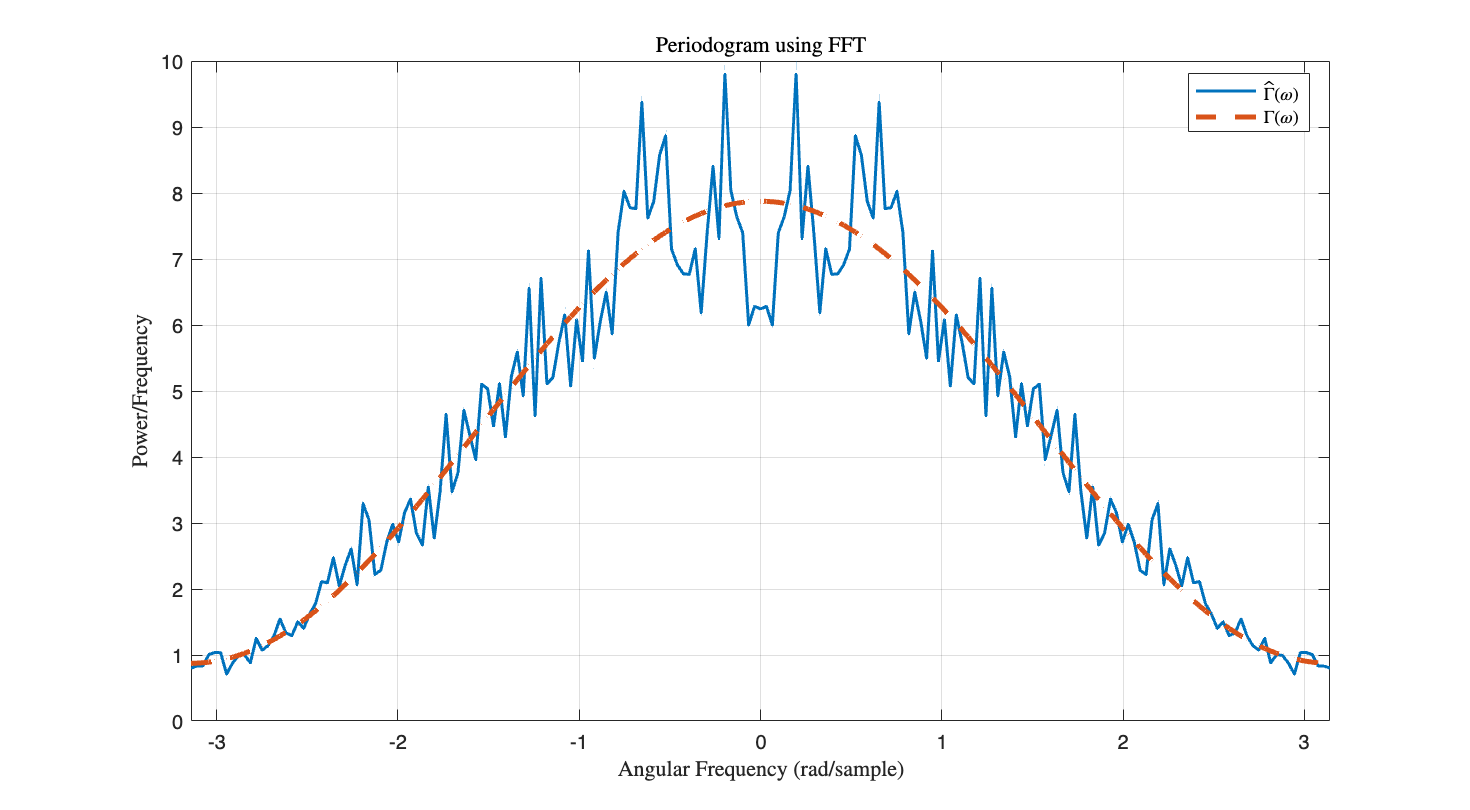

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);
plot(omegaPSD1,powerSpectrumMA1, 'LineStyle','-','LineWidth',1.5); % the estimated PSD
xlim([-pi, +pi]); % setting the extrema on the x-axis
grid on; hold on;
plot(omegaPSD1,PSDtrue, 'LineStyle','--','LineWidth',2.5); % the estimated PSD
xlabel("Angular Frequency (rad/sample)", 'Interpreter','latex');
ylabel("Power/Frequency", 'Interpreter','latex');
title("Periodogram using FFT", 'Interpreter','latex');
legend('$\hat{\Gamma}(\omega)$', '$\Gamma(\omega)$', 'Location','best', 'Interpreter', 'latex')

#### **Remark**

As written above, the periodogram is an estimate that can be very rough: this is the case. Compare with the theoretical spectrum.

#### The Spectrum of the Second MA Process

Given the samples, collected in the `array MA1`, let's apply the Eq. (++) to estimate the spectrum:

- Evaluate the DFT of the autocorrelation function estimate sequence

%WG_FFTd = fft(WGsamples);   % compute the FFT of the data sequence
MA2_FFT = fftshift(fft(gamma_v2));   % compute the FFT of the data sequence

                           % rearrange the array of the FFT, by shifting 
                           % the zero-frequency component to the 
                           % center of the array.

- Compute the power spectrum estimate according to Eq. (++).

**Proposal**: perform the spectrum estimation according to Eq. (*) [the periodogram] and compare the results.

powerSpectrumMA2 = abs(MA2_FFT); 
% squared magnitude, scaled by the number of samples Nstep
% and scaled also by the 


- Compute the corresponding angular frequencies

omegaPSD2 = linspace(-pi,pi,numel(gamma_v2)); 
% (2 pi)/Ndata is the angular frequency resolution for the spectrum
PSDtrue2 = (1+c_negMA.^2+2*c_negMA*cos(omegaPSD2))*varWG; 
% the theoretical spectrum, evaluated at the angular frequencies in omegaPSD1

- plotting the spectrum and compare with the theoreticla expression $\Gamma(\omega) = \, \left (1+c^2+ 2 c \cos \omega \right )
\lambda^2, \quad
\forall \, \omega \in [-\pi,\pi]$

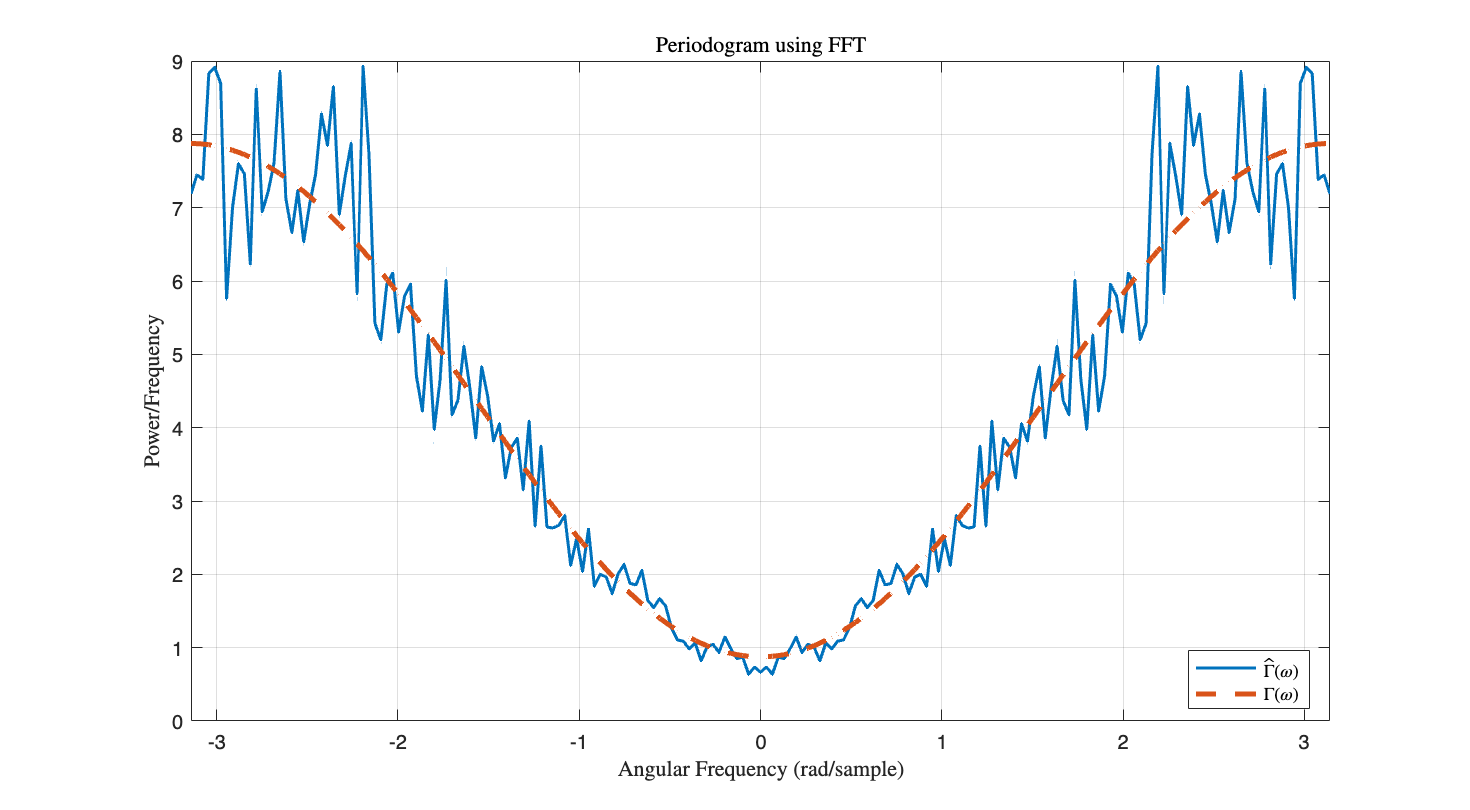

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);
plot(omegaPSD2,powerSpectrumMA2, 'LineStyle','-','LineWidth',1.5); % the estimated PSD
xlim([-pi, +pi]); % setting the extrema on the x-axis
grid on; hold on;
plot(omegaPSD2,PSDtrue2, 'LineStyle','--','LineWidth',2.5); % the estimated PSD
xlabel("Angular Frequency (rad/sample)", 'Interpreter','latex');
ylabel("Power/Frequency", 'Interpreter','latex');
title("Periodogram using FFT", 'Interpreter','latex');
legend('$\hat{\Gamma}(\omega)$', '$\Gamma(\omega)$', 'Location','best', 'Interpreter', 'latex')

#### **Remark**

As written above, the periodogram is an estimate that can be very rough: this is the case. Compare with the theoretical spectrum.

## References

[1] Proakis, John G. and Manolakis, Dimitris K.  * Digital Signal Processing (3rd Edition),* Prentice Hall,  1996.  